start = tic;
addpath functions\
addpath rawData\

systemName = 'ieee123'

systemName = 'ieee123'

actualBusNums = [1:36, 119, 126, 127, 117, 54:68, 122, 118, 37:53, 120, 125, 128, 69:116, 121, 123, 124]';
% actualBusNums = [1:36, 119, 126, 127, 117, 54:68, 122, 118, 37:53, 120, 125, 128, 69:116, 121, 123, 124, 129, 130, 131]';
N = max(actualBusNums);

loss_min = true;   % CVR  = 0, Loss minimization = 1;
itrMax = 150; %Max no. of permissible iterations for optimizing an area
% Stopping Criterion:
eps = 0.001 ; % Tolerance
displayTables = false;
displayNetworkGraphs = true;
displayActualBusNumbersInGraphs = true;

CVR = [0; 0]; %as opposed to [0.6; 3.0]

systemDataFolder = strcat("rawData/", systemName, "/");
connectionBusesFilename = strcat(systemDataFolder, "connectionBuses.txt");
CBTable = readtable(connectionBusesFilename)

CBTable = 3×3 table
    parentArea    childArea    connectingBus
    __________    _________    _____________

        1             2             40      
        1             3             41      
        2             4             19      


busDataActualBusNumsTable_Area = 41×6 table
    bus     P_L      Q_L     P_der    Q_der     busType
    ___    _____    _____    _____    ______    _______

     1         0        0      0           0       0   
     2         0        0      0           0       0   
     3     13.33    6.667      0      4.6655       0   
     4     6.667    3.333      0      2.3335       0   
     5         0        0      0           0       0   
     6     13.33    6.667      0      4.6655       0   
     7     6.667    3.333      0      2.3335       1   
     8     13.33    6.667      0      4.6655       0   
     9     6.667    3.333      0      2.3335       0   
    10         0        0      0           0       0   
    11     13.33    6.667      0      4.6655       0   
    12     6.667    3.3

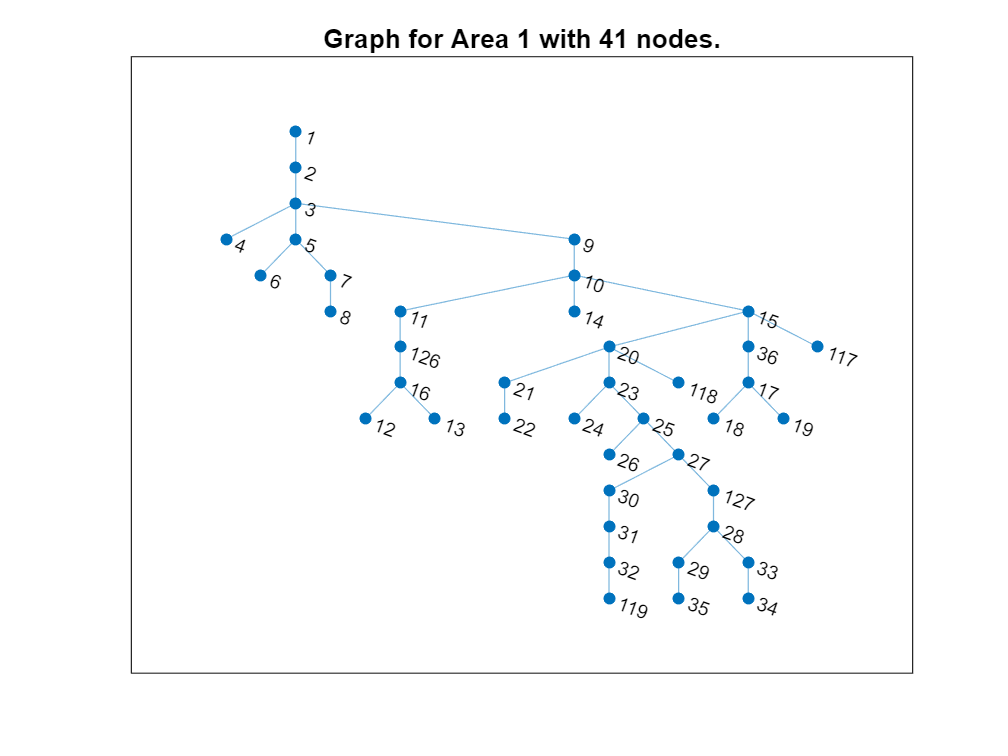

LP:                Optimal objective value is 0.000000.                                             


Optimal solution found.

No integer variables specified. Intlinprog solved the linear problem.



lenv2_Area = 41

lenv2 = 128

*************


Iteration: 0    Area: 1


busDataActualBusNumsTable_Area = 19×6 table
    bus     P_L      Q_L     P_der    Q_der     busType
    ___    _____    _____    _____    ______    _______

     15        0        0      0           0       0   
    117        0        0      0           0       0   
     54    13.33    6.667      0      4.6655       0   
     55    13.33    6.667      0      4.6655       0   
     56        0        0      0           0       0   
     57    6.667    3.333      0      2.3335       0   
     58    6.667    3.333      0      2.3335       1   
     59        0        0      0           0       0   
     60    6.667    3.333      0      2.3335       0   
     61    6.667    3.333      0      2.3335       0   
     62    6.667    3.333      0      2.3335       0   
     63        0       

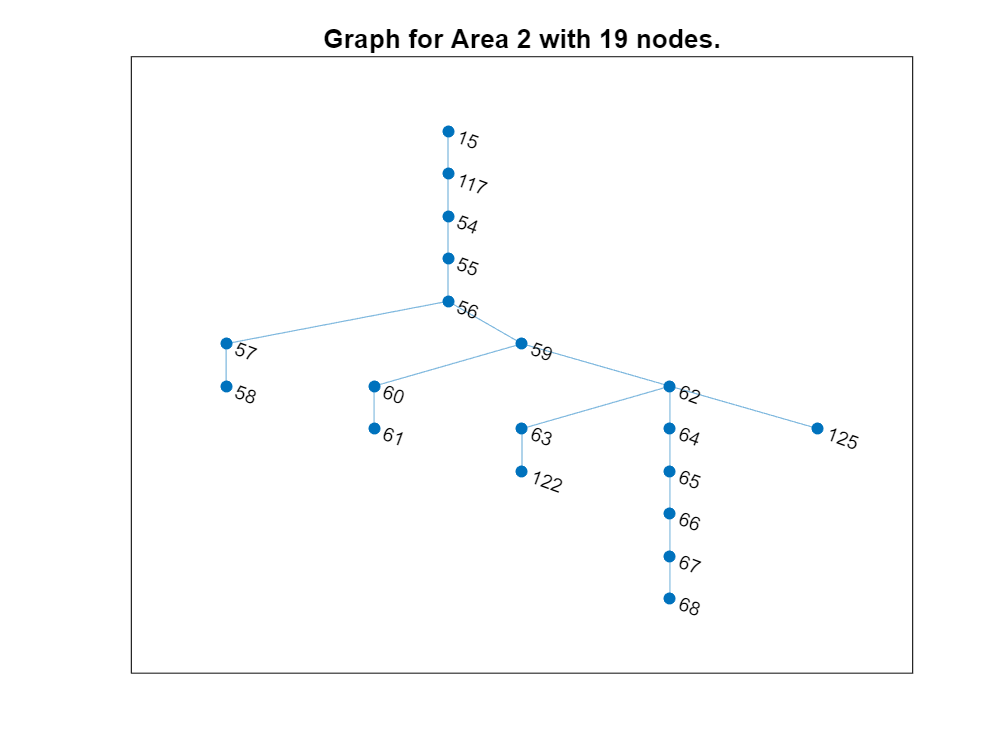

LP:                Optimal objective value is 0.000000.                                             


Optimal solution found.

No integer variables specified. Intlinprog solved the linear problem.



lenv2_Area = 19

lenv2 = 128

*************


Iteration: 0    Area: 2


busDataActualBusNumsTable_Area = 20×6 table
    bus     P_L      Q_L     P_der    Q_der     busType
    ___    _____    _____    _____    ______    _______

     20        0        0      0           0       0   
    118        0        0      0           0       0   
     37    13.33    6.667      0      4.6655       0   
     38        0        0      0           0       0   
     39    13.33    6.667      0      4.6655       1   
     40    6.667    3.333      0      2.3335       0   
     41    6.667    3.333      0      2.3335       2   
     42        0        0      0           0       0   
     43    6.667    3.333      0      2.3335       0   
     44    6.667    3.333      0      2.3335       0   
     45    13.33    6.667      0      4.6655       0   
     46        0       

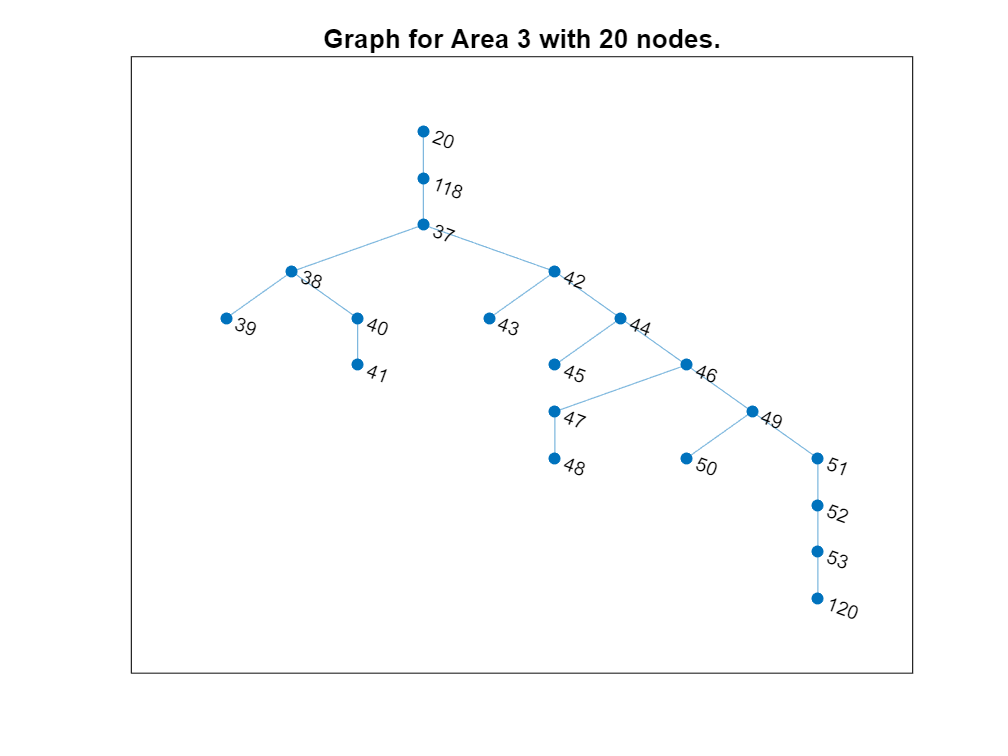

LP:                Optimal objective value is 0.000000.                                             


Optimal solution found.

No integer variables specified. Intlinprog solved the linear problem.



lenv2_Area = 20

lenv2 = 128

*************


Iteration: 0    Area: 3


busDataActualBusNumsTable_Area = 54×6 table
    bus     P_L      Q_L     P_der    Q_der     busType
    ___    _____    _____    _____    ______    _______

     62        0        0      0           0       0   
    125        0        0      0           0       0   
    128        0        0      0           0       0   
     69        0        0      0           0       0   
     70    6.667    3.333      0      2.3335       0   
     71    13.33    6.667      0      4.6655       0   
     72    6.667    3.333      0      2.3335       0   
     73    13.33    6.667      0      4.6655       0   
     74        0        0      0           0       0   
     75    13.33    6.667      0      4.6655       0   
     76    13.33    6.667      0      4.6655       0   
     77    13.33    6.6

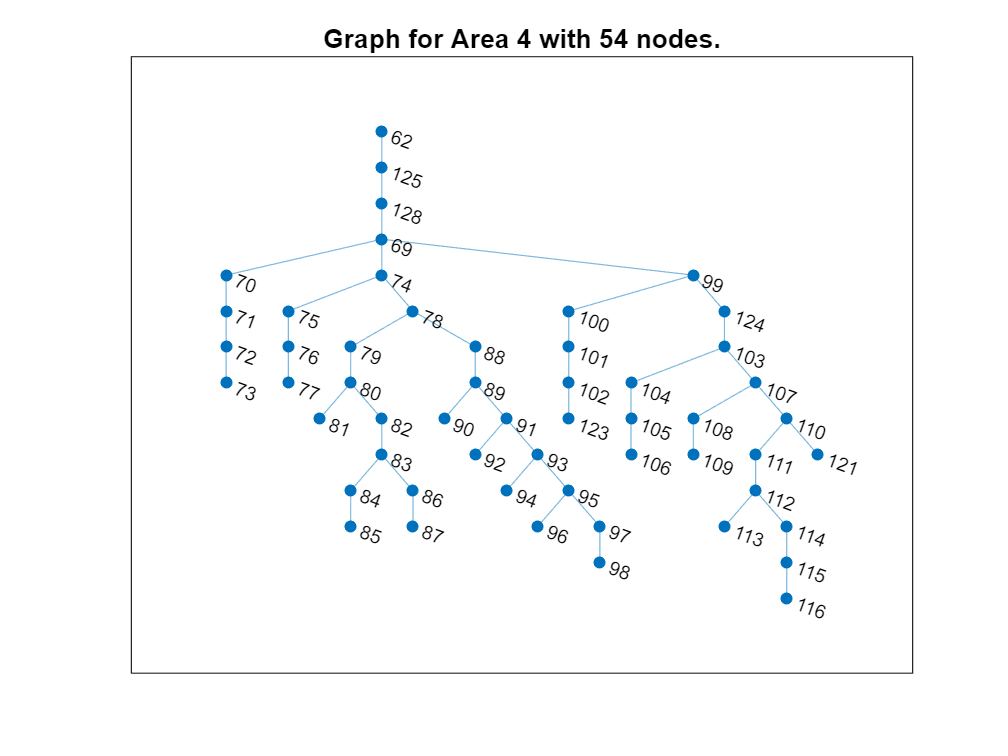

LP:                Optimal objective value is 0.000000.                                             


Optimal solution found.

No integer variables specified. Intlinprog solved the linear problem.



lenv2_Area = 54

lenv2 = 128

*************


Iteration: 0    Area: 4


busDataActualBusNumsTable_Area = 41×6 table
    bus     P_L      Q_L     P_der    Q_der     busType
    ___    _____    _____    _____    ______    _______

     1         0        0      0           0       0   
     2         0        0      0           0       0   
     3     13.33    6.667      0      4.6655       0   
     4     6.667    3.333      0      2.3335       0   
     5         0        0      0           0       0   
     6     13.33    6.667      0      4.6655       0   
     7     6.667    3.333      0      2.3335       1   
     8     13.33    6.667      0      4.6655       0   
     9     6.667    3.333      0      2.3335       0   
    10         0        0      0           0       0   
    11     13.33    6.667      0      4.6655       0   
    12     6.667    3.3

LP:                Optimal objective value is 0.000000.                                             


Optimal solution found.

No integer variables specified. Intlinprog solved the linear problem.



lenv2_Area = 41

lenv2 = 128

*************


Iteration: 1    Area: 1


busDataActualBusNumsTable_Area = 19×6 table
    bus     P_L      Q_L     P_der    Q_der     busType
    ___    _____    _____    _____    ______    _______

     15        0        0      0           0       0   
    117        0        0      0           0       0   
     54    13.33    6.667      0      4.6655       0   
     55    13.33    6.667      0      4.6655       0   
     56        0        0      0           0       0   
     57    6.667    3.333      0      2.3335       0   
     58    6.667    3.333      0      2.3335       1   
     59        0        0      0           0       0   
     60    6.667    3.333      0      2.3335       0   
     61    6.667    3.333      0      2.3335       0   
     62    6.667    3.333      0      2.3335       0   
     63        0       

LP:                Optimal objective value is 0.000000.                                             


Optimal solution found.

No integer variables specified. Intlinprog solved the linear problem.



lenv2_Area = 19

lenv2 = 128

*************


Iteration: 1    Area: 2


busDataActualBusNumsTable_Area = 20×6 table
    bus     P_L      Q_L     P_der    Q_der     busType
    ___    _____    _____    _____    ______    _______

     20        0        0      0           0       0   
    118        0        0      0           0       0   
     37    13.33    6.667      0      4.6655       0   
     38        0        0      0           0       0   
     39    13.33    6.667      0      4.6655       1   
     40    6.667    3.333      0      2.3335       0   
     41    6.667    3.333      0      2.3335       2   
     42        0        0      0           0       0   
     43    6.667    3.333      0      2.3335       0   
     44    6.667    3.333      0      2.3335       0   
     45    13.33    6.667      0      4.6655       0   
     46        0       

LP:                Optimal objective value is 0.000000.                                             


Optimal solution found.

No integer variables specified. Intlinprog solved the linear problem.



lenv2_Area = 20

lenv2 = 128

*************


Iteration: 1    Area: 3


busDataActualBusNumsTable_Area = 54×6 table
    bus     P_L      Q_L     P_der    Q_der     busType
    ___    _____    _____    _____    ______    _______

     62        0        0      0           0       0   
    125        0        0      0           0       0   
    128        0        0      0           0       0   
     69        0        0      0           0       0   
     70    6.667    3.333      0      2.3335       0   
     71    13.33    6.667      0      4.6655       0   
     72    6.667    3.333      0      2.3335       0   
     73    13.33    6.667      0      4.6655       0   
     74        0        0      0           0       0   
     75    13.33    6.667      0      4.6655       0   
     76    13.33    6.667      0      4.6655       0   
     77    13.33    6.6

LP:                Optimal objective value is 0.000000.                                             


Optimal solution found.

No integer variables specified. Intlinprog solved the linear problem.



lenv2_Area = 54

lenv2 = 128

*************


Iteration: 1    Area: 4


busDataActualBusNumsTable_Area = 41×6 table
    bus     P_L      Q_L     P_der    Q_der     busType
    ___    _____    _____    _____    ______    _______

     1         0        0      0           0       0   
     2         0        0      0           0       0   
     3     13.33    6.667      0      4.6655       0   
     4     6.667    3.333      0      2.3335       0   
     5         0        0      0           0       0   
     6     13.33    6.667      0      4.6655       0   
     7     6.667    3.333      0      2.3335       1   
     8     13.33    6.667      0      4.6655       0   
     9     6.667    3.333      0      2.3335       0   
    10         0        0      0           0       0   
    11     13.33    6.667      0      4.6655       0   
    12     6.667    3.3

LP:                Optimal objective value is 0.000000.                                             


Optimal solution found.

No integer variables specified. Intlinprog solved the linear problem.



lenv2_Area = 41

lenv2 = 128

*************


Iteration: 2    Area: 1


busDataActualBusNumsTable_Area = 19×6 table
    bus     P_L      Q_L     P_der    Q_der     busType
    ___    _____    _____    _____    ______    _______

     15        0        0      0           0       0   
    117        0        0      0           0       0   
     54    13.33    6.667      0      4.6655       0   
     55    13.33    6.667      0      4.6655       0   
     56        0        0      0           0       0   
     57    6.667    3.333      0      2.3335       0   
     58    6.667    3.333      0      2.3335       1   
     59        0        0      0           0       0   
     60    6.667    3.333      0      2.3335       0   
     61    6.667    3.333      0      2.3335       0   
     62    6.667    3.333      0      2.3335       0   
     63        0       

LP:                Optimal objective value is 0.000000.                                             


Optimal solution found.

No integer variables specified. Intlinprog solved the linear problem.



lenv2_Area = 19

lenv2 = 128

*************


Iteration: 2    Area: 2


busDataActualBusNumsTable_Area = 20×6 table
    bus     P_L      Q_L     P_der    Q_der     busType
    ___    _____    _____    _____    ______    _______

     20        0        0      0           0       0   
    118        0        0      0           0       0   
     37    13.33    6.667      0      4.6655       0   
     38        0        0      0           0       0   
     39    13.33    6.667      0      4.6655       1   
     40    6.667    3.333      0      2.3335       0   
     41    6.667    3.333      0      2.3335       2   
     42        0        0      0           0       0   
     43    6.667    3.333      0      2.3335       0   
     44    6.667    3.333      0      2.3335       0   
     45    13.33    6.667      0      4.6655       0   
     46        0       

LP:                Optimal objective value is 0.000000.                                             


Optimal solution found.

No integer variables specified. Intlinprog solved the linear problem.



lenv2_Area = 20

lenv2 = 128

*************


Iteration: 2    Area: 3


busDataActualBusNumsTable_Area = 54×6 table
    bus     P_L      Q_L     P_der    Q_der     busType
    ___    _____    _____    _____    ______    _______

     62        0        0      0           0       0   
    125        0        0      0           0       0   
    128        0        0      0           0       0   
     69        0        0      0           0       0   
     70    6.667    3.333      0      2.3335       0   
     71    13.33    6.667      0      4.6655       0   
     72    6.667    3.333      0      2.3335       0   
     73    13.33    6.667      0      4.6655       0   
     74        0        0      0           0       0   
     75    13.33    6.667      0      4.6655       0   
     76    13.33    6.667      0      4.6655       0   
     77    13.33    6.6

LP:                Optimal objective value is 0.000000.                                             


Optimal solution found.

No integer variables specified. Intlinprog solved the linear problem.



lenv2_Area = 54

lenv2 = 128

*************


Iteration: 2    Area: 4


busDataActualBusNumsTable_Area = 41×6 table
    bus     P_L      Q_L     P_der    Q_der     busType
    ___    _____    _____    _____    ______    _______

     1         0        0      0           0       0   
     2         0        0      0           0       0   
     3     13.33    6.667      0      4.6655       0   
     4     6.667    3.333      0      2.3335       0   
     5         0        0      0           0       0   
     6     13.33    6.667      0      4.6655       0   
     7     6.667    3.333      0      2.3335       1   
     8     13.33    6.667      0      4.6655       0   
     9     6.667    3.333      0      2.3335       0   
    10         0        0      0           0       0   
    11     13.33    6.667      0      4.6655       0   
    12     6.667    3.3

LP:                Optimal objective value is 0.000000.                                             


Optimal solution found.

No integer variables specified. Intlinprog solved the linear problem.



lenv2_Area = 41

lenv2 = 128

*************


Iteration: 3    Area: 1


busDataActualBusNumsTable_Area = 19×6 table
    bus     P_L      Q_L     P_der    Q_der     busType
    ___    _____    _____    _____    ______    _______

     15        0        0      0           0       0   
    117        0        0      0           0       0   
     54    13.33    6.667      0      4.6655       0   
     55    13.33    6.667      0      4.6655       0   
     56        0        0      0           0       0   
     57    6.667    3.333      0      2.3335       0   
     58    6.667    3.333      0      2.3335       1   
     59        0        0      0           0       0   
     60    6.667    3.333      0      2.3335       0   
     61    6.667    3.333      0      2.3335       0   
     62    6.667    3.333      0      2.3335       0   
     63        0       

LP:                Optimal objective value is 0.000000.                                             


Optimal solution found.

No integer variables specified. Intlinprog solved the linear problem.



lenv2_Area = 19

lenv2 = 128

*************


Iteration: 3    Area: 2


busDataActualBusNumsTable_Area = 20×6 table
    bus     P_L      Q_L     P_der    Q_der     busType
    ___    _____    _____    _____    ______    _______

     20        0        0      0           0       0   
    118        0        0      0           0       0   
     37    13.33    6.667      0      4.6655       0   
     38        0        0      0           0       0   
     39    13.33    6.667      0      4.6655       1   
     40    6.667    3.333      0      2.3335       0   
     41    6.667    3.333      0      2.3335       2   
     42        0        0      0           0       0   
     43    6.667    3.333      0      2.3335       0   
     44    6.667    3.333      0      2.3335       0   
     45    13.33    6.667      0      4.6655       0   
     46        0       

LP:                Optimal objective value is 0.000000.                                             


Optimal solution found.

No integer variables specified. Intlinprog solved the linear problem.



lenv2_Area = 20

lenv2 = 128

*************


Iteration: 3    Area: 3


busDataActualBusNumsTable_Area = 54×6 table
    bus     P_L      Q_L     P_der    Q_der     busType
    ___    _____    _____    _____    ______    _______

     62        0        0      0           0       0   
    125        0        0      0           0       0   
    128        0        0      0           0       0   
     69        0        0      0           0       0   
     70    6.667    3.333      0      2.3335       0   
     71    13.33    6.667      0      4.6655       0   
     72    6.667    3.333      0      2.3335       0   
     73    13.33    6.667      0      4.6655       0   
     74        0        0      0           0       0   
     75    13.33    6.667      0      4.6655       0   
     76    13.33    6.667      0      4.6655       0   
     77    13.33    6.6

LP:                Optimal objective value is 0.000000.                                             


Optimal solution found.

No integer variables specified. Intlinprog solved the linear problem.



lenv2_Area = 54

lenv2 = 128

*************


Iteration: 3    Area: 4


busDataActualBusNumsTable_Area = 41×6 table
    bus     P_L      Q_L     P_der    Q_der     busType
    ___    _____    _____    _____    ______    _______

     1         0        0      0           0       0   
     2         0        0      0           0       0   
     3     13.33    6.667      0      4.6655       0   
     4     6.667    3.333      0      2.3335       0   
     5         0        0      0           0       0   
     6     13.33    6.667      0      4.6655       0   
     7     6.667    3.333      0      2.3335       1   
     8     13.33    6.667      0      4.6655       0   
     9     6.667    3.333      0      2.3335       0   
    10         0        0      0           0       0   
    11     13.33    6.667      0      4.6655       0   
    12     6.667    3.3

LP:                Optimal objective value is 0.000000.                                             


Optimal solution found.

No integer variables specified. Intlinprog solved the linear problem.



lenv2_Area = 41

lenv2 = 128

*************


Iteration: 4    Area: 1


busDataActualBusNumsTable_Area = 19×6 table
    bus     P_L      Q_L     P_der    Q_der     busType
    ___    _____    _____    _____    ______    _______

     15        0        0      0           0       0   
    117        0        0      0           0       0   
     54    13.33    6.667      0      4.6655       0   
     55    13.33    6.667      0      4.6655       0   
     56        0        0      0           0       0   
     57    6.667    3.333      0      2.3335       0   
     58    6.667    3.333      0      2.3335       1   
     59        0        0      0           0       0   
     60    6.667    3.333      0      2.3335       0   
     61    6.667    3.333      0      2.3335       0   
     62    6.667    3.333      0      2.3335       0   
     63        0       

LP:                Optimal objective value is 0.000000.                                             


Optimal solution found.

No integer variables specified. Intlinprog solved the linear problem.



lenv2_Area = 19

lenv2 = 128

*************


Iteration: 4    Area: 2


busDataActualBusNumsTable_Area = 20×6 table
    bus     P_L      Q_L     P_der    Q_der     busType
    ___    _____    _____    _____    ______    _______

     20        0        0      0           0       0   
    118        0        0      0           0       0   
     37    13.33    6.667      0      4.6655       0   
     38        0        0      0           0       0   
     39    13.33    6.667      0      4.6655       1   
     40    6.667    3.333      0      2.3335       0   
     41    6.667    3.333      0      2.3335       2   
     42        0        0      0           0       0   
     43    6.667    3.333      0      2.3335       0   
     44    6.667    3.333      0      2.3335       0   
     45    13.33    6.667      0      4.6655       0   
     46        0       

LP:                Optimal objective value is 0.000000.                                             


Optimal solution found.

No integer variables specified. Intlinprog solved the linear problem.



lenv2_Area = 20

lenv2 = 128

*************


Iteration: 4    Area: 3


busDataActualBusNumsTable_Area = 54×6 table
    bus     P_L      Q_L     P_der    Q_der     busType
    ___    _____    _____    _____    ______    _______

     62        0        0      0           0       0   
    125        0        0      0           0       0   
    128        0        0      0           0       0   
     69        0        0      0           0       0   
     70    6.667    3.333      0      2.3335       0   
     71    13.33    6.667      0      4.6655       0   
     72    6.667    3.333      0      2.3335       0   
     73    13.33    6.667      0      4.6655       0   
     74        0        0      0           0       0   
     75    13.33    6.667      0      4.6655       0   
     76    13.33    6.667      0      4.6655       0   
     77    13.33    6.6

LP:                Optimal objective value is 0.000000.                                             


Optimal solution found.

No integer variables specified. Intlinprog solved the linear problem.



lenv2_Area = 54

lenv2 = 128

*************


Iteration: 4    Area: 4


busDataActualBusNumsTable_Area = 41×6 table
    bus     P_L      Q_L     P_der    Q_der     busType
    ___    _____    _____    _____    ______    _______

     1         0        0      0           0       0   
     2         0        0      0           0       0   
     3     13.33    6.667      0      4.6655       0   
     4     6.667    3.333      0      2.3335       0   
     5         0        0      0           0       0   
     6     13.33    6.667      0      4.6655       0   
     7     6.667    3.333      0      2.3335       1   
     8     13.33    6.667      0      4.6655       0   
     9     6.667    3.333      0      2.3335       0   
    10         0        0      0           0       0   
    11     13.33    6.667      0      4.6655       0   
    12     6.667    3.3

LP:                Optimal objective value is 0.000000.                                             


Optimal solution found.

No integer variables specified. Intlinprog solved the linear problem.



lenv2_Area = 41

lenv2 = 128

*************


Iteration: 5    Area: 1


busDataActualBusNumsTable_Area = 19×6 table
    bus     P_L      Q_L     P_der    Q_der     busType
    ___    _____    _____    _____    ______    _______

     15        0        0      0           0       0   
    117        0        0      0           0       0   
     54    13.33    6.667      0      4.6655       0   
     55    13.33    6.667      0      4.6655       0   
     56        0        0      0           0       0   
     57    6.667    3.333      0      2.3335       0   
     58    6.667    3.333      0      2.3335       1   
     59        0        0      0           0       0   
     60    6.667    3.333      0      2.3335       0   
     61    6.667    3.333      0      2.3335       0   
     62    6.667    3.333      0      2.3335       0   
     63        0       

LP:                Optimal objective value is 0.000000.                                             


Optimal solution found.

No integer variables specified. Intlinprog solved the linear problem.



lenv2_Area = 19

lenv2 = 128

*************


Iteration: 5    Area: 2


busDataActualBusNumsTable_Area = 20×6 table
    bus     P_L      Q_L     P_der    Q_der     busType
    ___    _____    _____    _____    ______    _______

     20        0        0      0           0       0   
    118        0        0      0           0       0   
     37    13.33    6.667      0      4.6655       0   
     38        0        0      0           0       0   
     39    13.33    6.667      0      4.6655       1   
     40    6.667    3.333      0      2.3335       0   
     41    6.667    3.333      0      2.3335       2   
     42        0        0      0           0       0   
     43    6.667    3.333      0      2.3335       0   
     44    6.667    3.333      0      2.3335       0   
     45    13.33    6.667      0      4.6655       0   
     46        0       

LP:                Optimal objective value is 0.000000.                                             


Optimal solution found.

No integer variables specified. Intlinprog solved the linear problem.



lenv2_Area = 20

lenv2 = 128

*************


Iteration: 5    Area: 3


busDataActualBusNumsTable_Area = 54×6 table
    bus     P_L      Q_L     P_der    Q_der     busType
    ___    _____    _____    _____    ______    _______

     62        0        0      0           0       0   
    125        0        0      0           0       0   
    128        0        0      0           0       0   
     69        0        0      0           0       0   
     70    6.667    3.333      0      2.3335       0   
     71    13.33    6.667      0      4.6655       0   
     72    6.667    3.333      0      2.3335       0   
     73    13.33    6.667      0      4.6655       0   
     74        0        0      0           0       0   
     75    13.33    6.667      0      4.6655       0   
     76    13.33    6.667      0      4.6655       0   
     77    13.33    6.6

LP:                Optimal objective value is 0.000000.                                             


Optimal solution found.

No integer variables specified. Intlinprog solved the linear problem.



lenv2_Area = 54

lenv2 = 128

*************


Iteration: 5    Area: 4


CBMatrix = table2array(CBTable);

numAreas = max(max(CBTable.parentArea, CBTable.childArea));

numChildAreas = zeros(numAreas, 1);
numRelationships = length(CBTable.parentArea);
isLeaf = ones(numAreas, 1);

for relationshipNum = 1:numRelationships
    parentArea = CBTable.parentArea(relationshipNum);
    isLeaf(parentArea, 1) = 0;
    childArea = CBTable.childArea(relationshipNum);
    numChildAreas(parentArea) = numChildAreas(parentArea) + 1; %contains which area has how many children
end

maxConnectingBusNum = max(CBTable.connectingBus);
S_allRelationships = zeros(length(CBTable.parentArea), 1);

S_parent = zeros(numAreas, 1);
S_child = zeros(N, numAreas);
v2_parent = 1.03^2*ones(numAreas, 1);
v2 = zeros(N, numAreas);
decisionVars = zeros(N, numAreas);
% Loop:

keepRunningIterations = 1;
itr = 0;
time_dist = zeros(itrMax, numAreas);
microIterationLosses = zeros(itrMax, numAreas);

%
while keepRunningIterations
    % Solve Areas parallelly:
    for Area = 1:numAreas

        v2_parent_Area = v2_parent(Area);
        S_childAreas = S_allRelationships(CBTable.parentArea == Area);
        isLeaf_Area = isLeaf(Area);

        [v2_Area, S_parent_Area, S_child_Area, ...
            microIterationLosses, decisionVars_Area, ...
            time_dist, R, T_Area, N_Area, busDataTable_Area, branchDataTable_Area] = ...
            NL_OPF_dist(v2_parent_Area, ...
            S_childAreas, ...
            Area, isLeaf_Area, CVR, systemDataFolder, ...
            microIterationLosses, time_dist, itr, ...
            CBTable, displayTables, displayNetworkGraphs, ...
            displayActualBusNumbersInGraphs);
        
        S_parent(Area) = S_parent_Area;
        lenv2_Area = size(v2_Area, 1)
        lenv2 = size(v2, 1)
        if lenv2_Area < lenv2
            v2_Area = [v2_Area; zeros(lenv2 - lenv2_Area, 1)];
            decisionVars_Area = [decisionVars_Area; zeros(lenv2 - lenv2_Area, 1)];
            lenDec_Var = size(decisionVars, 1);
            if lenv2 > lenDec_Var
                decisionVars = [decisionVars; zeros(lenv2 - lenDec_Var, numAreas)];
            end      
        elseif lenv2_Area > lenv2
            v2 = [v2; zeros(lenv2_Area - lenv2, numAreas)];
            lenDec_Var = size(decisionVars, 1);
            if lenv2_Area > lenDec_Var
                decisionVars = [decisionVars; zeros(lenv2_Area - lenDec_Var, numAreas)];
            end
        end
        
        if size(S_child_Area, 1) < size (S_child, 1)  % Ensuring the dimensions will match to store the S flow
            S_child_Area(end+1:size(S_child,1)) = 0;
            
        elseif size(S_child_Area, 1) > size (S_child, 1)
            S_child(end+1:size(S_child_Area,1),:) = 0;
        end
        
        decisionVars(:, Area) = decisionVars_Area;
        v2(:, Area) = v2_Area;   % Storing all the square of the node voltages
        S_child(:, Area) = S_child_Area;   % Storing all the S flow of the Area
        
        disp('*************')
        disp(['Iteration: ', num2str(itr), '    Area: ', num2str(Area)])
    end
    
    
    % Residual Matrix:
    keepRunningIterations = 0;
    R_max = zeros(itrMax, 1);
    for relationshipNum = 1:size(CBMatrix, 1)
        R = [
            (S_child((CBMatrix(relationshipNum,3)-1),CBMatrix(relationshipNum,1))) - (S_parent(CBMatrix(relationshipNum,2)));
            v2(CBMatrix(relationshipNum,3),CBMatrix(relationshipNum,1)) - v2_parent(CBMatrix(relationshipNum,2))];        
        if max(abs(R)) > R_max(itr+1)
            R_max(itr+1) = max(abs(R));
        end
    end
    if R_max(itr+1) > eps  % Checking if any boundary converged or not.
        keepRunningIterations = 1;
        a(1) = 0.25;
        a(2) = 0.05;
        %Communication-
        for relationshipNum = 1:size(CBMatrix,1)
            V_iter(itr+1,CBMatrix(relationshipNum,3),CBMatrix(relationshipNum,1)) = v2(CBMatrix(relationshipNum,3),CBMatrix(relationshipNum,1)) ;
            Se_iter(itr+1,CBMatrix(relationshipNum,2)) = S_parent(CBMatrix(relationshipNum,2));
            
            if itr>2
                v2_parent(CBMatrix(relationshipNum,2)) = a(2)*V_iter(itr-1,CBMatrix(relationshipNum,3),CBMatrix(relationshipNum,1))+...
                    a(1)*V_iter(itr,CBMatrix(relationshipNum,3),CBMatrix(relationshipNum,1))+...
                    (1-sum(a))*v2(CBMatrix(relationshipNum,3),CBMatrix(relationshipNum,1)) ;
                
                S_allRelationships(relationshipNum, 1) = a(2)*Se_iter(itr-1,CBMatrix(relationshipNum,2))+...
                    a(1)*Se_iter(itr,CBMatrix(relationshipNum,2))+...
                    (1-sum(a))*S_parent(CBMatrix(relationshipNum,2));
            else
                v2_parent(CBMatrix(relationshipNum,2)) = v2(CBMatrix(relationshipNum,3),CBMatrix(relationshipNum,1));
                S_allRelationships(relationshipNum, 1) = S_parent(CBMatrix(relationshipNum,2));
            end
        end
        itr = itr + 1;
    end
    if itr> itrMax
        keepRunningIterations = 0;
    end
    
end


disp('00000000000000')

00000000000000


V_node_sq = v2_parent(1);
Dec_Var_overall = 0;
for j = 1:numAreas
    v_area1 = v2(2:min(CBMatrix((find(j==CBMatrix(:,1))),3))-1,j);
    DV_area1 = decisionVars(2:min(CBMatrix((find(j==CBMatrix(:,1))),3))-1,j);
    
    if (isLeaf(j))
        end_node = min(find(v2(:,j)==0));
        if (end_node)
            v_area1 = v2(2:end_node-1,j);
            DV_area1 = decisionVars(2:end_node-1,j);
            
            disp('---')
        else
            v_area1 = v2(2:end,j);
            DV_area1 = decisionVars(2:end,j);
            disp('%%%%%%')
        end
    end
    node_size(j)= size(v_area1,1);
    V_node_sq = [V_node_sq;v_area1];
    Dec_Var_overall = [Dec_Var_overall;DV_area1 ];
    
    
end

---
---



for j = 1:length(actualBusNums)
    V_node_sq_1(actualBusNums(j),1) = V_node_sq(j);
    Dec_Var_overall_1(actualBusNums(j),1) = Dec_Var_overall(j);
end
%
v1 = (sqrt(V_node_sq_1))';
decisionVars = Dec_Var_overall_1';

microIterationLosses = microIterationLosses(1:itr, :);
dist_time = microIterationLosses(1:itr, :);

disp('------------------------------------------------------------')

------------------------------------------------------------


% if loss_min
disp(['Line Loss: ', num2str(sum(microIterationLosses(end, :)*1000)),' kW'])                       

Line Loss: 12.1761 kW


disp(['Substation Power: ', num2str(real(S_child(1))*1000),' kW']) 

Substation Power: 768.2385 kW


% end
disp(['Time to Solve: ', num2str(max(sum(time_dist))), 'sec'])

Time to Solve: 8.5487sec


disp('------------------------------------------------------------')

------------------------------------------------------------



elapsed = toc(start)

elapsed = 16.1319